clc, clear
addpath('fuctions')
load('net3.mat')

% imds_set 생성

[imds_set, label_set] = generate_image_set('..\images\train\');

% 각 클래스별 학습
featureLayer = 'loss3-classifier';
classifiers = train_concat_model(net,imds_set,featureLayer);

% 특징 추출
imds = imageDatastore('..\images\train\',"IncludeSubfolders",true,'LabelSource',"foldernames");
result = predict_concat_model(net, classifiers,imds,label_set,featureLayer);

X = table2array(result(:,1:end-1));
y = table2array(result(:,end));

% dummy value가 필요한 경우
% yy = dummyvar(y);


% % FNN
layers = [
    featureInputLayer(10,"Name","featureinput")
    fullyConnectedLayer(50,"Name","fc_1")
    fullyConnectedLayer(100,"Name","fc_2")
    fullyConnectedLayer(50,"Name","fc_4")
    fullyConnectedLayer(10,"Name","fc_3")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")];
options = trainingOptions('adam', ...
    'Plots','training-progress');

fnn_net = trainNetwork(X,y, layers,options)

단일 GPU에서 훈련합니다.


｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　Ｅｐｏｃｈ　　｜　　반복　횟수　　｜　　　　경과　시간　　　　　｜　　미니　배치　정확도　　｜　　미니　배치　손실　　｜　　기본　학습률　　｜
｜　　　　　　　　　｜　　　　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　｜　　　　　　　　　　　　｜　　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜


｜　　　　　　　１　｜　　　　　　　１　｜　　　　　００：００：０４　｜　　　　　　　６．２５％　｜　　　　　３．１５９６　｜　　　０．００１０　｜


｜　　　　　　　４　｜　　　　　　５０　｜　　　　　００：００：０５　｜　　　　　　４０．６３％　｜　　　　　１．７０１６　｜　　　０．００１０　｜


｜　　　　　　　７　｜　　　　　１００　｜　　　　　００：００：０６　｜　　　　　　４９．２２％　｜　　　　　１．５３２３　｜　　　０．００１０　｜


｜　　　　　　１０　｜　　　　　１５０　｜　　　　　００：００：０７　｜　　　　　　５１．５６％　｜　　　　　１．４１５０　｜　　　０．００１０　｜


｜　　　　　　１４　｜　　　　　２００　｜　　　　　００：００：０７　｜　　　　　　５１．５６％　｜　　　　　１．４１０３　｜　　　０．００１０　｜


｜　　　　　　１７　｜　　　　　２５０　｜　　　　　００：００：０８　｜　　　　　　５２．３４％　｜　　　　　１．２６６２　｜　　　０．００１０　｜


｜　　　　　　２０　｜　　　　　３００　｜　　　　　００：００：０９　｜　　　　　　５３．１３％　｜　　　　　１．３４２３　｜　　　０．００１０　｜


｜　　　　　　２４　｜　　　　　３５０　｜　　　　　００：００：１０　｜　　　　　　５２．３４％　｜　　　　　１．３４１４　｜　　　０．００１０　｜


｜　　　　　　２７　｜　　　　　４００　｜　　　　　００：００：１０　｜　　　　　　５７．０３％　｜　　　　　１．２４８０　｜　　　０．００１０　｜


｜　　　　　　３０　｜　　　　　４５０　｜　　　　　００：００：１１　｜　　　　　　５３．９１％　｜　　　　　１．２６２１　｜　　　０．００１０　｜


｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜


fnn_net =   SeriesNetwork - 속성 있음:

         Layers: [7×1 nnet.cnn.layer.Layer]
     InputNames: {'featureinput'}
    OutputNames: {'classoutput'}



% 여기까지가 학습

% train 정확도
predict_train = classify(fnn_net,X);
accuracy = sum(predict_train==y)/length(y)

accuracy = 0.5160

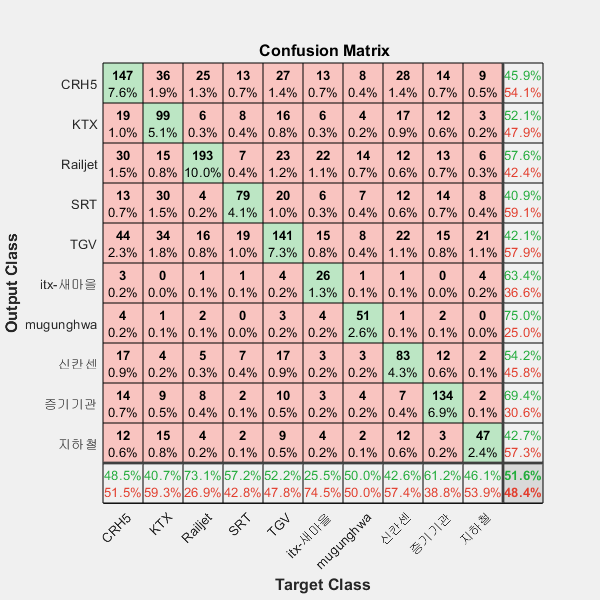

plotconfusion(y,predict_train)

% test 정확도
imds_te = imageDatastore('..\images\validation\',"IncludeSubfolders",true,'LabelSource',"foldernames");


result_test = predict_concat_model(net, classifiers,imds_te,label_set,featureLayer);
X_test = table2array(result_test(:,1:end-1));
y_test = table2array(result_test(:,end));

predict_test = classify(fnn_net,X_test);
accuracy = sum(predict_test==y_test)/length(y_test)

accuracy = 0.1700

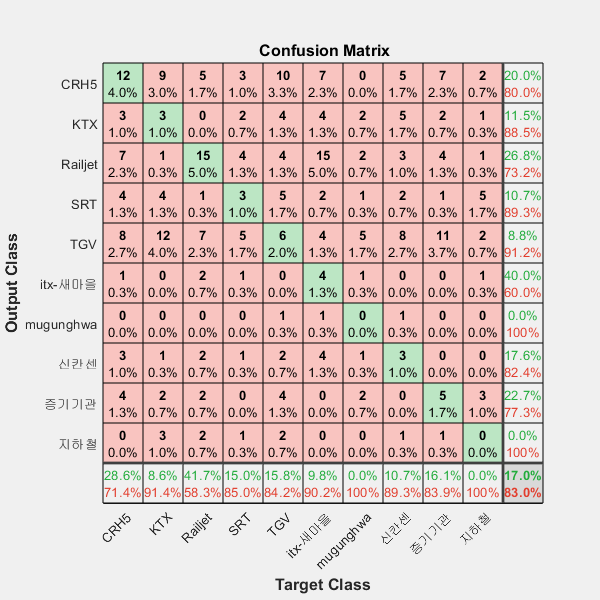

plotconfusion(y_test, predict_test)